# EDGE DETECTION

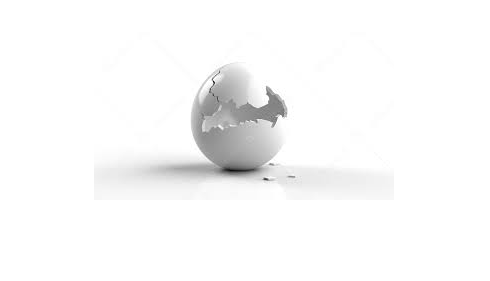

img=imread("images.jpg");
img=rgb2gray(img);

imshow(img)

## CANNY

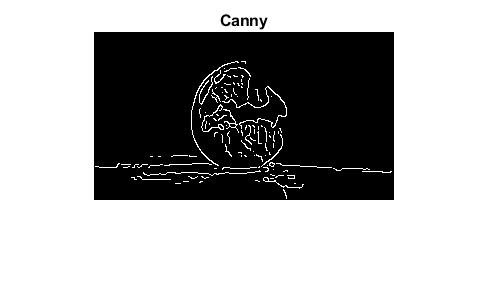

edg1=edge(img,"canny");
figure,imshow(edg1)
title("Canny")

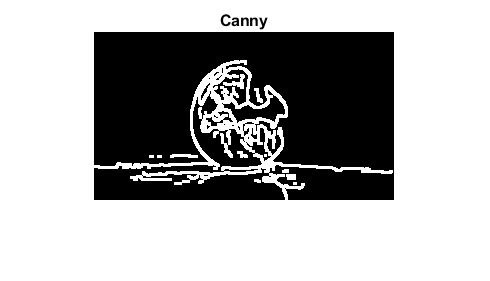


edge11= wiener2(edg1,[3 3]);
figure,imshow(edge11)
title("Canny")

## SOBEL

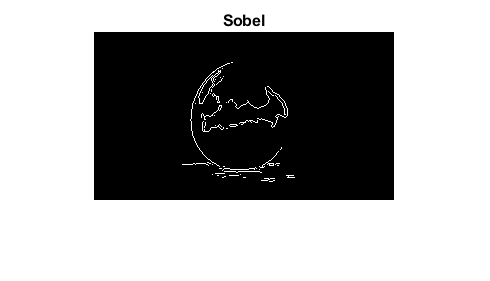

edg2=edge(img,"Sobel");
figure,imshow(edg2)
title("Sobel")

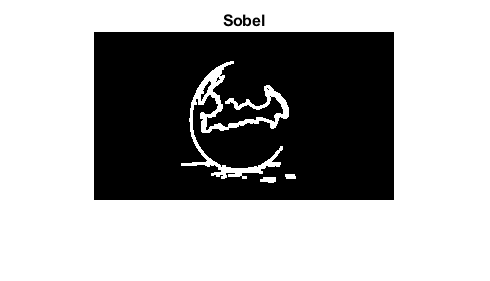

edge22= wiener2(edg2,[3 3]);
figure,imshow(edge22)
title("Sobel")

## LOG

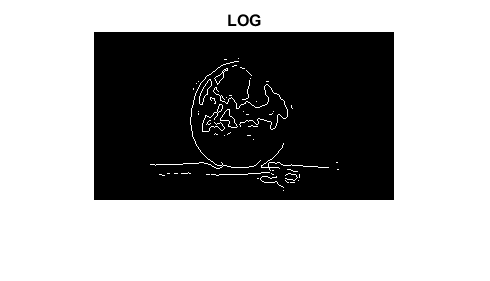

edg3=edge(img,"log");
figure,imshow(edg3)
title("LOG")

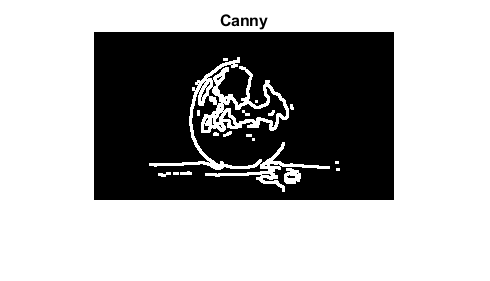

edge33= wiener2(edg3,[3 3]);
figure,imshow(edge33)
title("Canny")

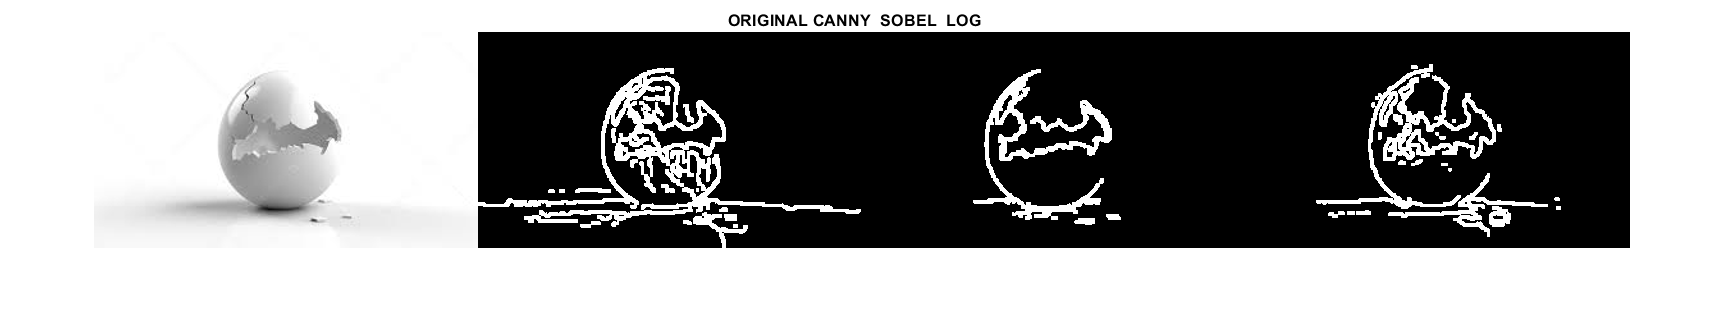

figure,montage({img,edge11,edge22,edge33},"size",[1 4])
title("ORIGINAL CANNY  SOBEL  LOG   ")